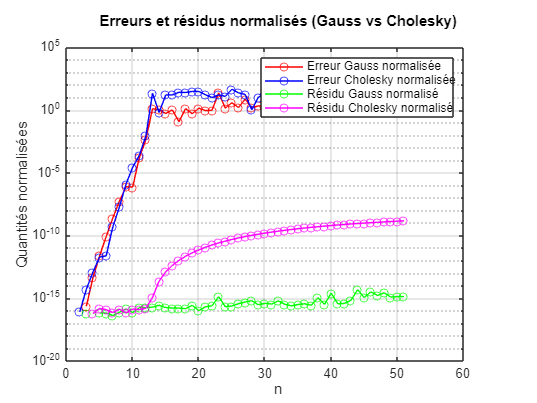


% Initialisations:
n_values = 2:51; 
errors_gauss_normed = zeros(length(n_values), 1);
errors_cholesky_normed = zeros(length(n_values), 1);
residuals_gauss_normed = zeros(length(n_values), 1);
residuals_cholesky_normed = zeros(length(n_values), 1);
kappa2_values = zeros(length(n_values), 1);  % Initialisation pour le conditionnement spectral

% On boucle sur les valeurs de n
for idx = 1:length(n_values)
    n = n_values(idx);
    
    % On génére la matrice de Hilbert d'ordre n
    H = hilb(n);  
    cond_H = cond(H);  % Calcul du conditionnement de H
    
    % Calcul du vecteur b
    b = zeros(n, 1);
    for i = 1:n
        b(i) = 1/i + 1/(i+1);
    end
    
    % Résolution par élimination de Gauss sans pivotage (i=0)
    c_gauss = Gausselim(H, b, 0);  
    
    % Résolution par décomposition de Cholesky
    L = Cholesky(H);
    y = forsub(L, b);  % Résolution Ly = b
    c_cholesky = backsub(L', y);  % Résolution L'x = y
    
    % Solution exacte
    c_exact = H \ b;  
    
    % Calcul des erreurs de Gauss et Cholesky
    e_gauss = c_exact - c_gauss; 
    e_cholesky = c_exact - c_cholesky; 
    
    % Calcul des résidus pour Gauss et Cholesky
    r_gauss = b - H * c_gauss; 
    r_cholesky = b - H * c_cholesky; 
    
    % Normalisation des erreurs et des résidus
    errors_gauss_normed(idx) = norm(e_gauss) / norm(c_exact);
    errors_cholesky_normed(idx) = norm(e_cholesky) / norm(c_exact);
    
    residuals_gauss_normed(idx) = norm(r_gauss) / norm(b);
    residuals_cholesky_normed(idx) = norm(r_cholesky) / norm(b);
    
    % Calcul du conditionnement spectral de H
    [U, S, V] = svd(H);  
    cond_H = max(diag(S)) / min(diag(S));  % Calcul du nombre de conditionnement
    
    % On enregistre la valeur du conditionnement spectral
    kappa2_values(idx) = cond_H;  
    
end

% Affichage des erreurs et des résidus normalisés
figure;
semilogy(n_values, errors_gauss_normed, 'r-o', 'DisplayName', 'Erreur Gauss normalisée');
hold on;
semilogy(n_values, errors_cholesky_normed, 'b-o', 'DisplayName', 'Erreur Cholesky normalisée');
semilogy(n_values, residuals_gauss_normed, 'g-o', 'DisplayName', 'Résidu Gauss normalisé');
semilogy(n_values, residuals_cholesky_normed, 'm-o', 'DisplayName', 'Résidu Cholesky normalisé');
xlabel('n');
ylabel('Quantités normalisées');
legend;
title('Erreurs et résidus normalisés (Gauss vs Cholesky)');
grid on;

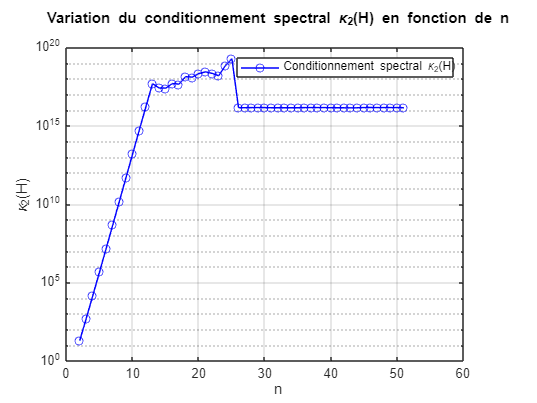


% Affichage du conditionnement spectral
figure;
semilogy(n_values, kappa2_values, 'b-o', 'DisplayName', 'Conditionnement spectral \kappa_2(H)');
xlabel('n');
ylabel('\kappa_2(H)');
legend;
title('Variation du conditionnement spectral \kappa_2(H) en fonction de n');
grid on;

a) Comparer la précision de la méthode d’élimination de Gauss et de Cholesky. Quelles différences dans les résultats auriez-vous observées si vous aviez utilisé la méthode d’élimination de Gauss avec pivotage partiel? Pourquoi?:

Les courbes des erreurs pour la méthode de Gauss sans pivotage et celle de Cholesky suivent une trajectoire similaire. Pour des valeurs de n faibles, les erreurs sont très petites (∼=10**−16), mais elles augmentent rapidement à mesure que n augmente, atteignant un plateau autour de 10**0. En particulier, l'erreur de Gauss sans pivotage reste légèrement inférieure à celle de Cholesky pour n>12. Cette augmentation des erreurs peut être expliquée par le mauvais conditionnement de la matrice de Hilbert H, qui amplifie les erreurs numériques. Le conditionnement de la matrice H devient de plus en plus mauvais à mesure que n croît, ce qui entraîne des erreurs de calcul plus importantes.

Si l’on utilisait la méthode de Gauss avec pivotage partiel, on pourrait s'attendre à ce que les erreurs restent faibles un peu plus longtemps (pour n≈20), car le pivotage stabilise les calculs en évitant les divisions par des petits nombres. Toutefois, même avec pivotage partiel, l’instabilité numérique finirait par apparaître pour des n plus grands, car le pivotage ne peut pas annuler complètement les effets du mauvais conditionnement de la matrice H.

b) Expliquer le comportement des erreurs relatives lorsque n augmente:

Lorsque n augmente, les erreurs relatives croissent de manière dramatique, ce qui est lié à la dégradation du conditionnement de la matrice de Hilbert H. Ce phénomène est illustré par le graphique du conditionnement spectral κ2(H), qui montre une explosion exponentielle à mesure que n augmente. Un mauvais conditionnement signifie que de petites erreurs d’arrondi dans les calculs intermédiaires peuvent entraîner des erreurs considérables dans la solution finale. C’est pourquoi les méthodes de Gauss sans pivotage et de Cholesky, qui sont toutes deux sensibles au conditionnement de la matrice, suivent de près la variation de κ2(H)�.

De plus, les opérations successives impliquées dans les méthodes numériques comme Gauss sans pivotage et Cholesky accumulent les erreurs, rendant les solutions calculées (Gauss� et Cholesky�) de moins en moins précises. Cholesky, basé sur une factorisation H=LLT, devient instable pour des matrices mal conditionnées, et Gauss sans pivotage est encore plus affecté par les petits pivots. Cependant, pour des n élevés, les deux méthodes tendent vers des erreurs comparables, car leurs limites respectives sont atteintes face au mauvais conditionnement. Ainsi, on devrait utiliser des méthodes exactes au lieu de méthodes itératives qui peuvent être plus rapides pour H.

c)  Comment est-ce possible que les erreurs relatives soient beaucoup plus grandes que les résidus relatifs? :

Les erreurs relatives peuvent être beaucoup plus grandes que les résidus relatifs en raison des erreurs d'arrondi et du mauvais conditionnement de la matrice. Un résidu faible indique que la solution approximative satisfait bien l'équation Ax=b, mais cela ne garantit pas que cette solution soit proche de la solution exacte. En effet, ona que pour une matrice A non singuliere et x, b! =0: ∥*x*∥∥*x*−*xe*�∥�≤∥*A*∥⋅∥*A*−1∥⋅∥*r*∥/||b|| Cela montre que, même si le résidu est faible par rapport à b, un mauvais conditionnement de la matrice peut amplifier l'erreur relative. Ainsi, dans des matrices mal conditionnées, les erreurs numériques dans les calculs sont amplifiées, rendant l'erreur relative beaucoup plus grande que le résidu relatif.� Par conséquent, un résidu faible ne signifie pas nécessairement une petite erreur relative, car l'amplification des erreurs numériques dues au mauvais conditionnement peut rendre l'écart par rapport à la solution exacte beaucoup plus grand.

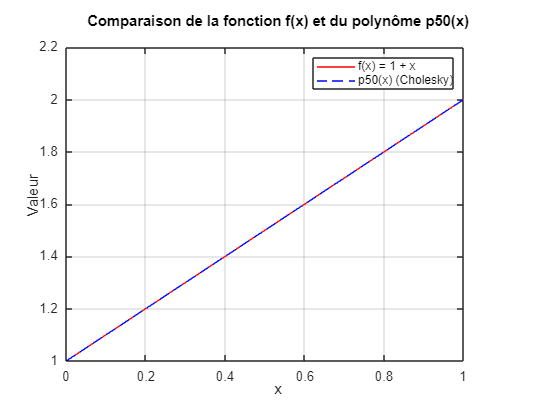


% On défini l'intervalle
x = linspace(0, 1, 100);  % Crée un vecteur de 100 points entre 0 et 1

% Notre fct:
f_x = 1 + x;

% On calcule le polynôme p50(x) à partir des coefficients c_cholesky
p50_x = zeros(size(x));
for i = 1:length(c_cholesky)
    p50_x = p50_x + c_cholesky(i) * x.^(i-1);  % On somme les termes du polynôme
end

% Tracer f(x) et p50(x)
figure;
plot(x, f_x, 'r-', 'DisplayName', 'f(x) = 1 + x');
hold on;
plot(x, p50_x, 'b--', 'DisplayName', 'p50(x) (Cholesky)');
xlabel('x');
ylabel('Valeur');
legend;
title('Comparaison de la fonction f(x) et du polynôme p50(x)');
grid on;

Ce graphique montre qu'on a une excellente approximation de la fonction linéaire par le polynôme de degré 50. La méthode de Cholesky permet donc une interpolation fidèle de cette fonction car le tracer est pratiquement identique à la fonction d'origine sur l'intervalle [0,1].